# MECH3465 | Coursework 2: Template

Replace the template title with your teams number!

## CW2: Coursework 2 - ** Robot Librarian!**

This coursework template is split into the 5 sections of the coursework.

**If you haven't read the brief then please download it from minerva**

You should explain your process during each stage, and each section of code you include should contain a short description of what you are doing and an overview of any MATLAB functions you have used and why.

### Add your own sub-headings to each main section!

This will keep things organised.

### Comment your code!

Before you say anything, I will admit my code has been quite poorly commented in some cases throughout the practicals, don't be like me, comment your code!

clear % Clear workspace variables 

## 0. Loading the Scenario

Download the URDF file from Minerva and save it somewhere, be aware that if you all work on the code together the file path may change depending on who's PC you are using and where they have saved the files!

You should change my default filepath, this will not work on your PC...

clear

Create a [`robotScenario`](docid:robotics_ref#mw_146ff228-e368-41e9-ac10-b70d38e44bd8) object.

scenario = robotScenario(UpdateRate=1,StopTime=10);

Create a [`rigidBodyTree`](docid:robotics_ref#bvan8uq-1) object of the custom CW2 URDF.

rmpath("C:\Users\georg\Documents\MATLAB\CW2_Complete_Robot_URDF_2025_V5\urdf")

addpath("C:\Users\georg\Documents\MATLAB\CW2_Complete_Robot_URDF_2025_V6\urdf") % Add the filepath for where you saved the URDF

robotRBT = importrobot("CW2_Complete_Robot_URDF_2025_V6.urdf");
showdetails(robotRBT)

--------------------
Robot: (1 bodies)

 Idx      Body Name           Joint Name           Joint Type      Parent Name(Idx)   Children Name(s)
 ---      ---------           ----------           ----------      ----------------   ----------------
   1        Library        Library_Fixed                fixed          Base_Link(0)   
--------------------


Create a `rigidBodyTree`-based [`robotPlatform`](docid:robotics_ref#mw_184989ef-41a5-4055-a8a4-5460899dbc3a) object using the manipulator model.

robot = robotPlatform("Manipulator",scenario, ...
                      RigidBodyTree=robotRBT);

Create collision objects for all 6 books. - DO NOT EDIT BOOK POSITIONS IN THIS SECTION

book_1 = robotPlatform("Book_1",scenario,Collision="mesh", InitialBaseOrientation=[0.706923132	0.706925728	0.016057751	0.016057692], InitialBasePosition=[0.014018	-0.30839	0.10381]);
updateMesh(book_1,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0 0])

book_2 = robotPlatform("Book_2",scenario,Collision="mesh", InitialBaseOrientation=[0.706747289	0.706749885	0.022504157	0.022504074], InitialBasePosition=[-0.019668	0.30852	-0.032738]);
updateMesh(book_2,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0.682 0])
 
book_3 = robotPlatform("Book_3",scenario,Collision="mesh", InitialBaseOrientation=[0.40083391	0.400835382	-0.582522818	-0.582520678], InitialBasePosition=[0.28417	-0.10873	-0.082996]);
updateMesh(book_3,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 1 0])

book_4 = robotPlatform("Book_4",scenario,Collision="mesh", InitialBaseOrientation=[0.206562054	0.206562812	0.676264476	0.676261992], InitialBasePosition=[-0.16721	-0.24817	0.32703]);
updateMesh(book_4,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[0 1 0])

book_5 = robotPlatform("Book_5",scenario,Collision="mesh", InitialBaseOrientation=[0.636410903	0.636413241	0.308188293	0.308187161], InitialBasePosition=[-0.24541	0.19397	0.10258]);
updateMesh(book_5,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[0 1 1])

book_6 = robotPlatform("Book_6",scenario,Collision="mesh", InitialBaseOrientation=[0.276366618	0.276367633	0.650863095	0.650860704], InitialBasePosition=[-0.22945	-0.22148	0.10258]);
updateMesh(book_6,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0 1])


Visualize the scenario.

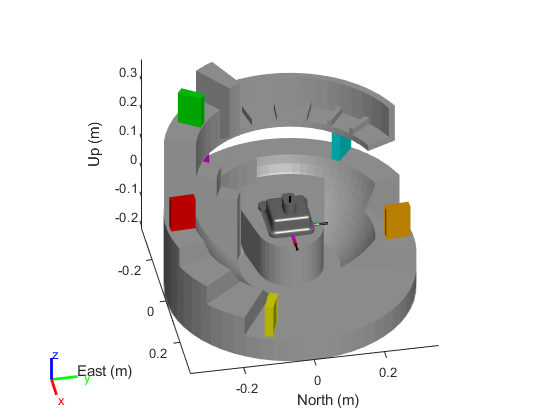

hold off
[ax,plotFrames] = show3D(scenario,Collisions="off");
axis equal
hold on
view(79,36)
light

## 1. Forward Kinematics

### 1.1 Approach Overview

Write an overview of your approach to this main task here, and then continue to add comments to any code-sections you create to help explain the process.

Code comments, code-section text, figures, and presentation are all counted towards explanation marks.

### 1.2 Labelled Denavit-Hartenberg Frame Diagram

Download the CW2_Robot_Dimensions.PDF from Minerva and use it to solve the forward kinematics of the robot using the Denavit-Hartenberg assignment method. For more information look at back at the lecture on Forward Kinematics, it has a breakdown of the solutions.

Insert your nice diagram here.

### 1.3 Specify D-H Parameters and Produce a Table


$$\textrm{dhparams}=\left\lbrack A_{i\;} /a_{i\;} \;\;\;\;\;|\;\;\alpha_{i\;} \;\;\;\;\;\;|\;\;\;\;d_{i\;} \;\;\;\;|\;\;\;\;\theta {\;}_{i\;} \right\rbrack$$


% Copied over from RP04, use this for loop to add your robot from DH
% parameters, this is currently based on the 6DOF example, edit this for
% your robots parameters.

dhparams = [0   	pi/2	0   	0;
            0.4318	0       0       0;
            0.0203	-pi/2	0.15005	0;
            0   	pi/2	0.4318	0;
            0       -pi/2	0   	0;
            0       0       0       0] % Show this output in your final file

dhparams =          0    1.5708         0         0
    0.4318         0         0         0
    0.0203   -1.5708    0.1500         0
         0    1.5708    0.4318         0
         0   -1.5708         0         0
         0         0         0         0


## 2. Build Robot in MATLAB Robotics Toolbox

% Copied over from RP04, use this for loop to add your robot from DH
% parameters, this is currently based on the 6DOF example, edit this for
% your robots parameters.

bodies = cell(6,1);
joints = cell(6,1);
for i = 1:6
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(Robot,bodies{i},"Base_Link")
    else % Add current body to previous body by name
        addBody(Robot,bodies{i},bodies{i-1}.Name)
    end
end



showdetails(Robot)

--------------------
Robot: (15 bodies)

 Idx      Body Name      Joint Name      Joint Type      Parent Name(Idx)   Children Name(s)
 ---      ---------      ----------      ----------      ----------------   ----------------
   1        Link_B1        Joint_B1           fixed          Base_Link(0)   
   2        Link_B2        Joint_B2           fixed          Base_Link(0)   
   3        Link_B3        Joint_B3           fixed          Base_Link(0)   
   4        Link_B4        Joint_B4           fixed          Base_Link(0)   
   5        Link_B5        Joint_B5           fixed          Base_Link(0)   
   6        Link_B6        Joint_B6           fixed          Base_Link(0)   
   7        Link_B7        Joint_B7           fixed          Base_Link(0)   
   8        Link_B8        Joint_B8           fixed          Base_Link(0)   
   9        Link_B9        Joint_B9           fixed          Base_Link(0)   
  10          body1            jnt1        revolute          Base_Link(0)   body

### Adding Robot Visuals

clearVisual(Robot.Bodies{1,15}) % Clear body visuals if you make a mistake
addVisual(Robot.Bodies{1,15},"sphere",[0.005], trvec2tform([0,0,0]))



**Reference: **For more shapes check out [checkCollision](https://uk.mathworks.com/help/robotics/ref/checkcollision.html#mw_4edbbc38-d51a-4356-94c6-68be8bb54566)

### Changing Robot Visual Colours

Not really important to marking but you can personilse your robots a bit further using this bit of code,

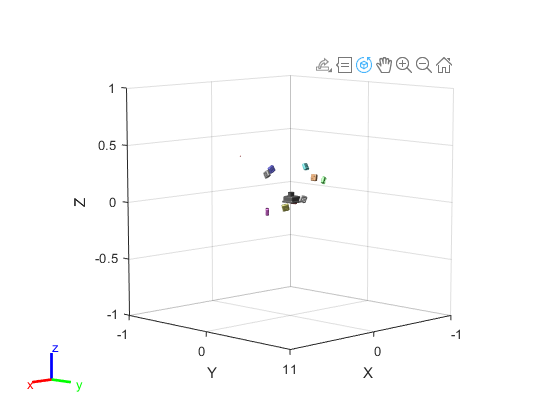

% I found a way to change visual mesh colours using property inspector and findall
% There's probably a better way, let me know if you find a command to set mesh colour on adding! 
% If you want to me to go through how I did this then just ask.
ax = show(Robot, "Frames","off", "Collisions","off", "Visuals","on"); % Check robot loaded correctly

gfx_body6_mesh = findall(ax, 'DisplayName', 'body6_mesh'); % Grab mesh name handle
set(gfx_body6_mesh, 'FaceColor', [1 0.5 0.5]); % Change colour

### Adding Robot Collisions 

showdetails(Robot)

--------------------
Robot: (15 bodies)

 Idx      Body Name      Joint Name      Joint Type      Parent Name(Idx)   Children Name(s)
 ---      ---------      ----------      ----------      ----------------   ----------------
   1        Link_B1        Joint_B1           fixed          Base_Link(0)   
   2        Link_B2        Joint_B2           fixed          Base_Link(0)   
   3        Link_B3        Joint_B3           fixed          Base_Link(0)   
   4        Link_B4        Joint_B4           fixed          Base_Link(0)   
   5        Link_B5        Joint_B5           fixed          Base_Link(0)   
   6        Link_B6        Joint_B6           fixed          Base_Link(0)   
   7        Link_B7        Joint_B7           fixed          Base_Link(0)   
   8        Link_B8        Joint_B8           fixed          Base_Link(0)   
   9        Link_B9        Joint_B9           fixed          Base_Link(0)   
  10          body1            jnt1        revolute          Base_Link(0)   body

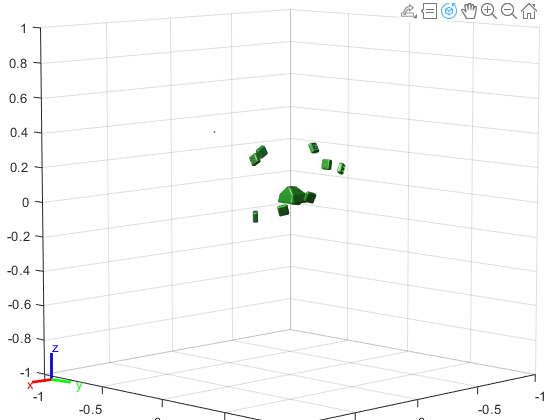


ax = show(Robot, "Frames","off", "Collisions","on"); % Check robot loaded correctly


% Add collison to the end effector of your robot
addCollision(Robot.Bodies{1,15},"sphere",[0.005], trvec2tform([0,0,0])) % add new collision
addVisual(Robot.Bodies{1,15},"sphere",[0.005], trvec2tform([0,0,0]))

isColliding = checkCollision(Robot,homeConfiguration(Robot),SkippedSelfCollisions="parent")

isColliding = logical
   0


% Possibly useful functions: 
% clearCollision(Robot.Bodies{1,15})

 **Reference: **For more shapes check out [checkCollision](https://uk.mathworks.com/help/robotics/ref/checkcollision.html#mw_4edbbc38-d51a-4356-94c6-68be8bb54566)

**NOTE: **If you choose to generate a URDF then you do not need to perform many of these steps.

## 3. Inverse Kinematics

Starting in the home configuration, solve for the arm reaching the point where the Book_1 frame lies.

###     3.1 Explain your Approach 

 explain your approach to solving the inverse kinematics problem and any assumptions or simplifications you have made. How does this robot compare to our 3DOF examples?

###     3.2 Solve Analytically 

Make sure you document the code in each step! As with all tasks you do not have to complete this all in one code section, feel free to break it up.

## 4. Trajectory Generation

Generate a trajectory for your End-Effector to follow such that the robots Tool Centre Point presses each of the books in the correct order. (20%)

###     4.1 Explain your approach 

Explain your approach to trajectory generation between each waypoint/via **(Max 200 words).**

###     4.2 Generate Theta Matrix

Matrix of theta values containing your robots joint angle data to be plotted in your animation.

## 5. Create your Animation/Video/Recording

You're on the home straight now!

It's time to prove your MATLAB plotting skills and generate the greatest gif you will ever create ...*within a MATLAB coding environment.*

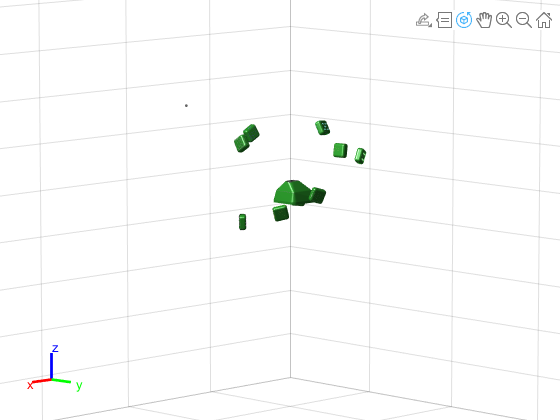


% Remove the button from the rigidBodyTree once it has been pressed
% removeBody(Robot,"Link_B1") % Example code to remove button body


% Gif stuff: Look up previous gif based practicals for guidance!
    exportgraphics(gcf,'PleaseReviewTheModule.gif','Append',true);

    w = warning('query','last');
    id = w.identifier;
    warning('off',id);

**NOTE: **I have not tested gif generation with this new scenario tool, we may need to use screen capture this year. Which will actaully speed matlab up, so that would be nice!

## Submission Instructions and Deadline

**Deadline: **Week 23 - Thursday @15:00 - 01/05/2025

**You will submit:**

- The complete code of your solution as a MATLAB Live Script, please also include outputs (e.g. do not clear the outputs after processing)

- Please, export your MATLAB Live Script as a PDF with the same file name. Only include outputs that are necessary to explain your process or those that show important milestones in the coursework (basically, please don't output everything making the document huge)

- Please refer to the hadnout for further instructions.

**MECH3465 CW2 2025 **| Written by ***George Jackson-Mills***

*Email: ****G.Jackson-Mills@Leeds.ac.uk***

Last edited: 18/03/2025